# Manipulator Short project: Skull tumor surgery

## Carlso Bergillos, Xavier Martín

**List of to do:**

The Robotic environment must contain:

1.- Operating table. It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Use 'patch' or 'fill3' functions to model it.

*We use the patch function to draw the 2 tables. We also set up the view.*

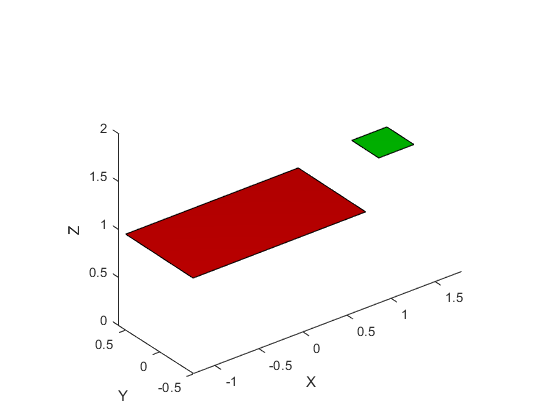

tool_offset = [0, 0, 0.2];
table_h = 1.0;
table_length = 2.5;
table_width = 1.0;
t1_x = [-table_length/2 table_length/3.5 table_length/3.5 -table_length/2];
t1_y = [-table_width/2 -table_width/2 table_width/2 table_width/2];
t1_z = [table_h table_h table_h table_h];

patch(t1_x,t1_y,t1_z,'red')

toolt_origin = [1.4 0.2 table_h];
toolt_size = [0.4 0.4 0];
t2_x = [toolt_origin(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)+toolt_size(1) toolt_origin(1)];
t2_y = [toolt_origin(2) toolt_origin(2) toolt_origin(2)+toolt_size(2) toolt_origin(2)+toolt_size(2)];
t2_z = [toolt_origin(3) toolt_origin(3) toolt_origin(3) toolt_origin(3)];

patch(t2_x,t2_y,t2_z,'green')

axis([-2 2 -2 2 0 4]), axis('equal');
camlight('headlight');
material('dull');
xlabel('X'), ylabel('Y'), zlabel('Z')
hold on

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*We load the vertices and faces from Human_body.obj and display it in the scene. *

*We scale, rotate and translate the vertices to place the body correctly on the table.*

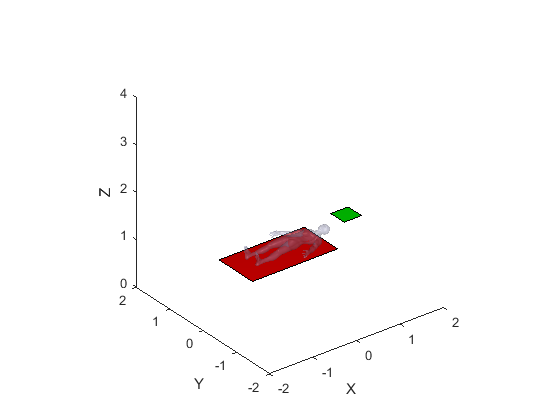

[VB,FB] = readOBJ('Human_body.obj','Quads',true);
person_height = 1.8;
VB = VB .* (person_height/max(VB(:, 2)));
VB = [VB ones(size(VB, 1), 1)];
VB = transl(-person_height/2, 0, table_h-min(VB(:, 3)))*trotz(-90, 'deg')*VB';
VB = (VB(1:3, :))';
p = patch('Faces',FB,'Vertices',VB, 'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15, ...
         'FaceAlpha', 0.25);
axis([-2 2 -2 2 0 4]);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*We obtain the reference frame for the skull, and the reference frame for the images. Then we load the coordinates for the fiducials in Image space and transform them to World space.*

*This commented section below draws the Crani.stl model in the scene. For performance reasons we have disabled it.*

RFC = transl(person_height/2-0.11,-0.005,table_h+0.1425)*troty(90, 'deg')*trotz(-90, 'deg')*trscale(0.001);
% [VS,FS] = stlRead('Crani.stl');
% VS2 = h2e(RFC*e2h(VS'))';
% 
% p = patch('Faces',FS,'Vertices',VS2, 'FaceColor',       [0.2 1 0.2], ...
%          'EdgeColor',       'none',        ...
%          'FaceLighting',    'flat',     ...
%          'AmbientStrength', 0.95, ...
%          'FaceAlpha', 0.75);

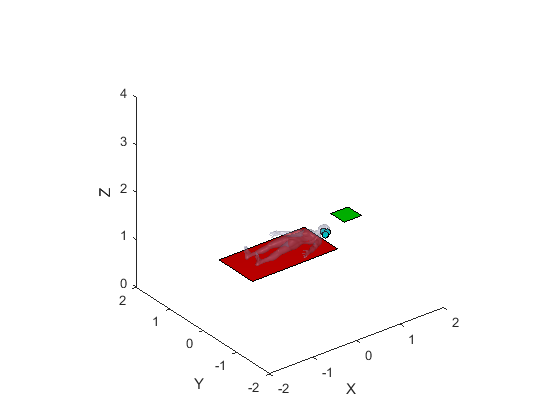

RFI = RFC * trscale(1, 1, 1.4) * troty(180, 'deg') * transl(-125, -145, -65);
fiducidals = load('fiducidals.csv');
fiducidals = h2e(RFI * e2h(fiducidals'))';

scatter3(fiducidals(:, 1), fiducidals(:, 2), fiducidals(:, 3), 24, ...
    'MarkerEdgeColor','k', ...
    'MarkerFaceColor',[0 .75 .75])  

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*We load the coordinates of the tumor points in Image space.*

tumor = load('tumor.csv');

t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

trplot(RFC, 'length', 100, 'color', 'b', 'frame', 'C')
trplot(RFI, 'length', 100, 'color', 'k', 'frame', 'I')

RFT = transl(toolt_origin);
trplot(RFT, 'length', 0.5, 'color', 'g', 'frame', 'T')

RFTPerson = transl(t1_x(1),t1_y(1),t1_z(1))

RFTPerson =     1.0000         0         0   -1.2500
         0    1.0000         0   -0.5000
         0         0    1.0000    1.0000
         0         0         0    1.0000


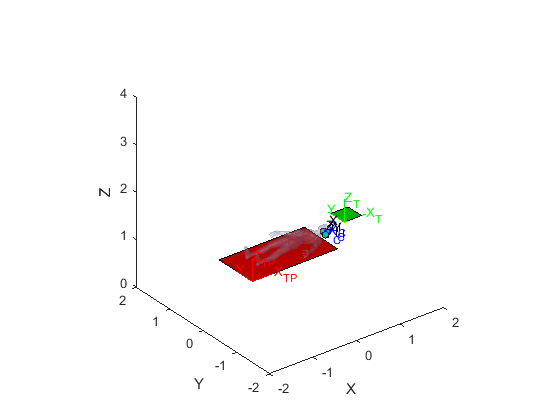

trplot(RFTPerson, 'length', 0.5, 'color', 'r', 'frame', 'TP')

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

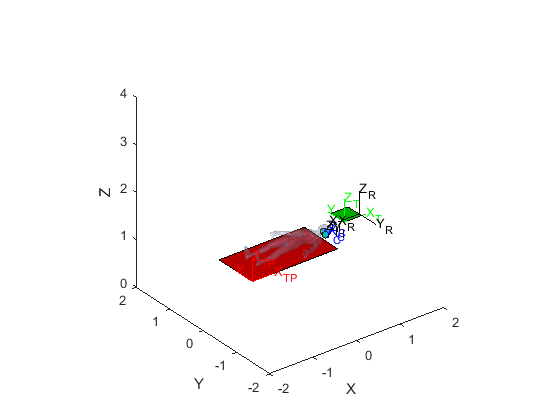

mdl_puma560
RFR = transl(1.6, 0, 1.2) * trotz(180, 'deg');

p560.tool = SE3(tool_offset);
p560.base = RFR;

trplot(RFR, 'length', 0.5, 'color', 'k', 'frame', 'R')

7.- Get the transformation that maps tumor points in Robot Frame.

*We obtain the transformation matrix from RFR to RFI (ItoR).*

*Then we apply this transformation to all the tumor points in Image space to obtain the points' coordinates in Robot space. To obtain them in World space, we apply the RFR transformation (from Robot space to World space).*

ItoR = inv(RFR) * RFI;

pointR = h2e(ItoR * e2h(tumor'))';
pointWR = h2e(RFR * e2h(pointR'))';
tumor = pointWR;

8.- Print the tumor points in Robot Frame.

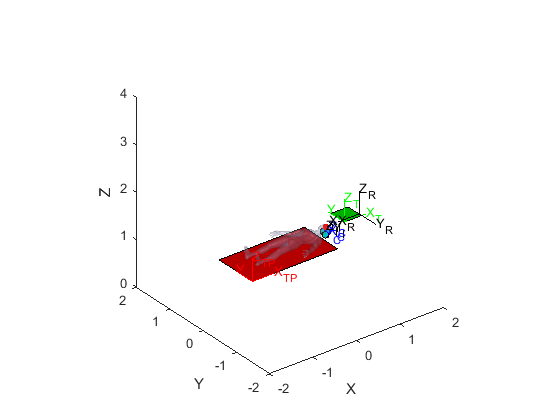

scatter3(pointWR(:, 1), pointWR(:, 2), pointWR(:, 3), 12, 'r', 'filled')

pointR

pointR =     0.7526    0.0040   -0.0055
    0.7526   -0.0050   -0.0165
    0.7540    0.0060   -0.0035
    0.7540   -0.0070   -0.0185
    0.7554    0.0080   -0.0025
    0.7554   -0.0100   -0.0195
    0.7568    0.0090   -0.0005
    0.7568   -0.0120   -0.0205
    0.7582    0.0090    0.0005
    0.7582   -0.0130   -0.0235


9.- Prepare a script that perform a biopsy. Zoom in the scene

type task_changeTool


% This set of instructions change the tool being used (by going to the
% table, simulating it picks a tool, and returning to the default pose).

tool_pos = toolt_size./2;

t1 = [0:0.05:5];
t2 = [0:0.05:0.5];

tool_posW = h2e(RFT * e2h(tool_pos'))';

T_tool = transl(tool_posW) * trotz(0, 'deg') * trotx(180, 'deg');

T_tool_start = transl(0, 0, 0.1) * T_tool;
trplot(T_tool, 'length', 0.5, 'color', 'k', 'frame', 'R')

%% Trajectory 1: qn -> tool start
q_tool_start = p560.ikine6s(T_tool_start, 'run');
traj_1 = jtraj(qn, q_tool_start, t1);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: tool start -> pick tool
Ts = ctraj(T_tool_start, T_tool, length(t2)); 
traj_2 = p560.ikine6s(Ts, 'run');

p560.plot(traj_2, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2R: pick tool -> tool start
traj_2r = flipud(traj_2);

p560.plot(traj_2r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 1R: pick tool -> qn
traj_1r = f

type task_biopsy


%This set of instructions perform a biopsy.

tumor_center = mean(tumor(:, :));

t = [0:0.05:5]';

T_biopsy_end = transl(tumor_center) * troty(-135, 'deg');
T_biopsy_start = T_biopsy_end * transl(0, 0, -0.2);

%% Trajectory 1: qn -> biopsy start
q_biopsy_start = p560.ikine6s(T_biopsy_start, 'run');
traj_1 = jtraj(qn, q_biopsy_start, t);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: biopsy
Ts = ctraj(T_biopsy_start, T_biopsy_end, length(t)); 
traj_2 = p560.ikine6s(Ts, 'run');
traj_2r = flipud(traj_2);
traj_2loop = [traj_2; traj_2r];

p560.plot(traj_2loop, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 1R: biopsy start -> qn
traj_1r = flipud(traj_1);

p560.plot(traj_1r, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)


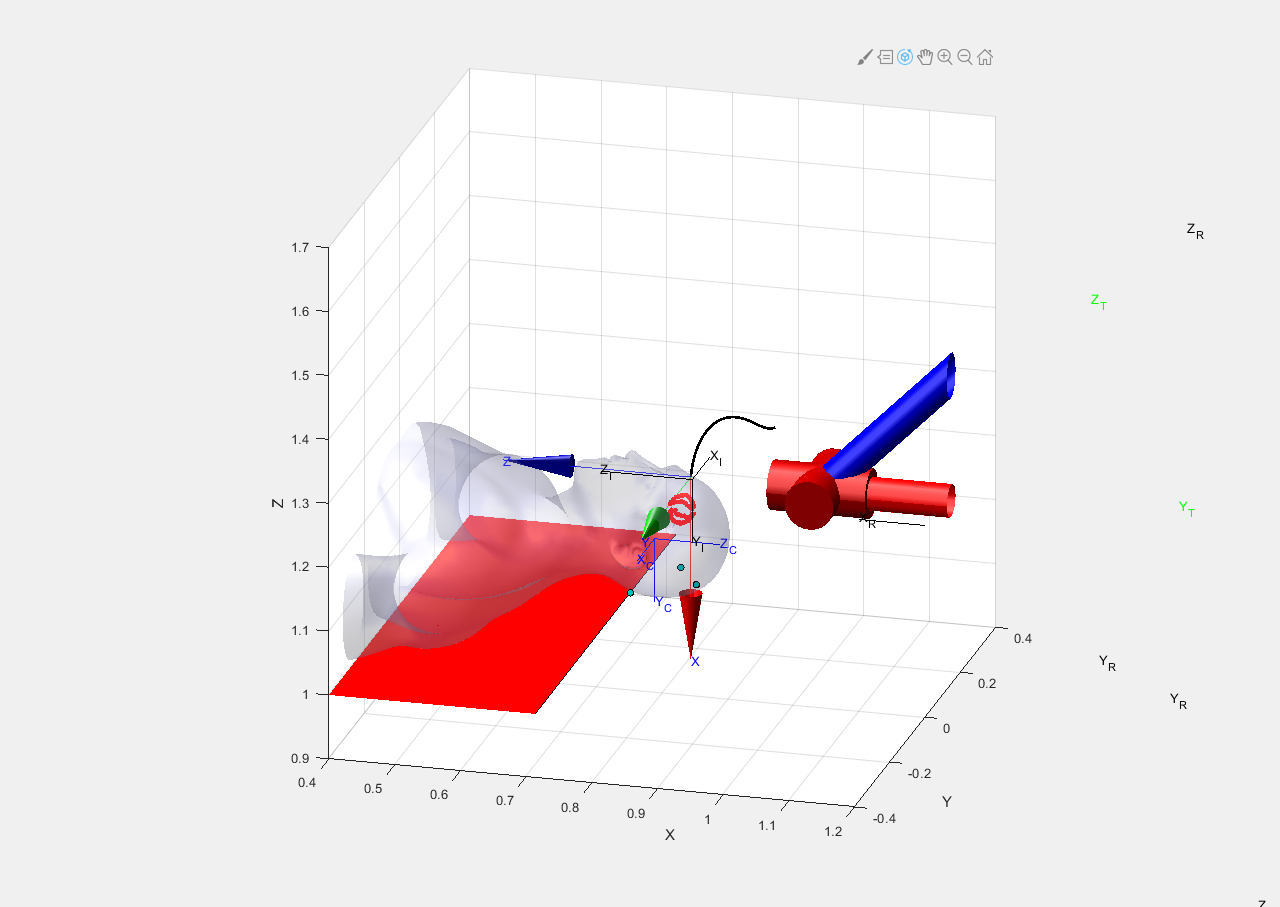


view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_biopsy

10.- Prepare a script that perform trepanation.

type task_trepanation


% This set of instructions perform a trepanation (a circle with a 45 degree
% angle of incidence).

t = [0:0.05:5]';

radius = compute_radius(tumor) - 0.002;
tumor_center = mean(tumor(:, :));
T_trepanation = transl(tumor_center) * transl(0.06, 0, 0) * troty(70, 'deg');

Ts_trepanation = zeros(4, 4, length(t));

for i=1:length(t)
    a = (t(i)/t(end))*(2*pi);
    c = [cos(a)*radius
         sin(a)*radius
         0];
    Ts_trepanation(:,:,i) = transl(c) *  trotz(a+pi)* troty(-45, 'deg') * trotx(180, 'deg');
    Ts_trepanation(:,:,i) = T_trepanation * Ts_trepanation(:,:,i);
    Ts_trepanation(:,:,i) = Ts_trepanation(:,:,i);
end

%% Trajectory 1: qn -> trepanation pre
T_trepanation_start = Ts_trepanation(:, :, 1);
T_trepanation_pre = T_trepanation_start * transl(0, 0, -0.1);
q_trepanation_pre = p560.ikine6s(T_trepanation_pre, 'run');
traj_1 = jtraj(qn, q_trepanation_pre, t);

p560.plot(traj_1, 'fps', 60, 'trail', {'k', 'LineWidth', 2}, 'zoom', 2)

%% Trajectory 2: trepanation pre -> tre

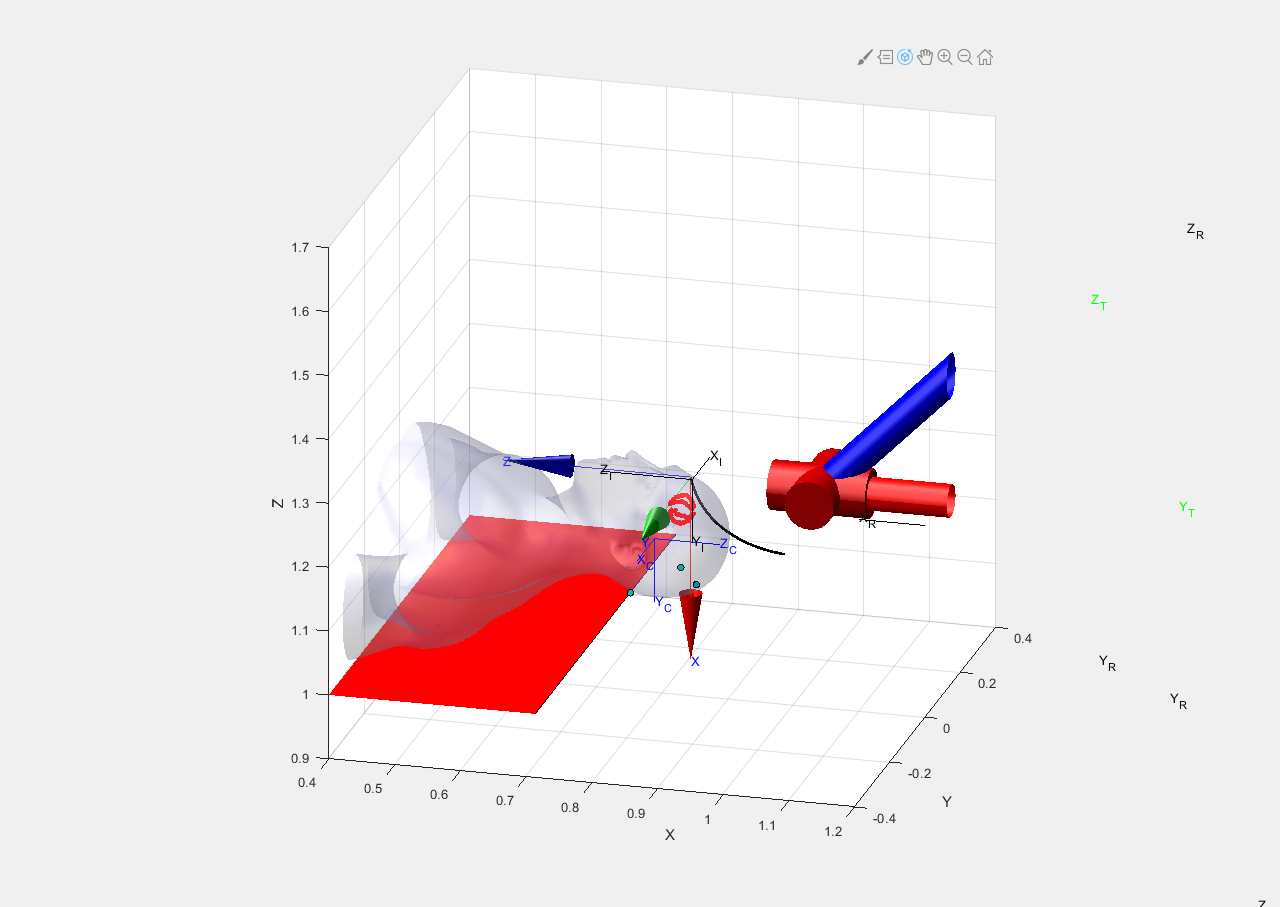


view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_trepanation

11.- Prepare a script that perform tumor burning with the laser.

type task_burningLaser


% This set of instructions burn the tumor with a laser tool. The hole is no necessary to be big, the surgeons forecast half
% radius of the tumor equivalent sphere. To burn the tumor, assume the tool irradiate heat like a
% sphere shape of 4mm radius. Take care not burn healthy biological tissues.

tumor = pointWR;
t = [0:0.05:5]';

[mean_radius, radiusX, radiusY, radiusZ] = compute_radius(tumor);
radiusX = radiusX * 0.7071 - 0.004; %1/sqrt(2)
radiusY = radiusY * 0.7071 - 0.004; %1/sqrt(2)
radiusZ = radiusZ * 0.7071 - 0.004; %1/sqrt(2)

vX = 0.004;
vY = 0.004;
vZ = 0.004;
radius = mean_radius ./ 2;
tumor_center = mean(tumor(:, :));
T_trepanation = transl(tumor_center) * transl(0.06, 0, 0) * troty(70, 'deg');

Ts_trepanation = zeros(4, 4, length(t));

diameterX = radiusX * 2;
diameterY = radiusY * 2;
diameterZ = radiusZ * 2;

a = 1;
t_x = (ceil(diameterX/0.004));
t_y = (ceil(diameterY/0.004));
t_z = (ceil(diameterZ/0.004));

for i = 0:t_x
   for j = 0:t_y
        for k = 0:t_z
        

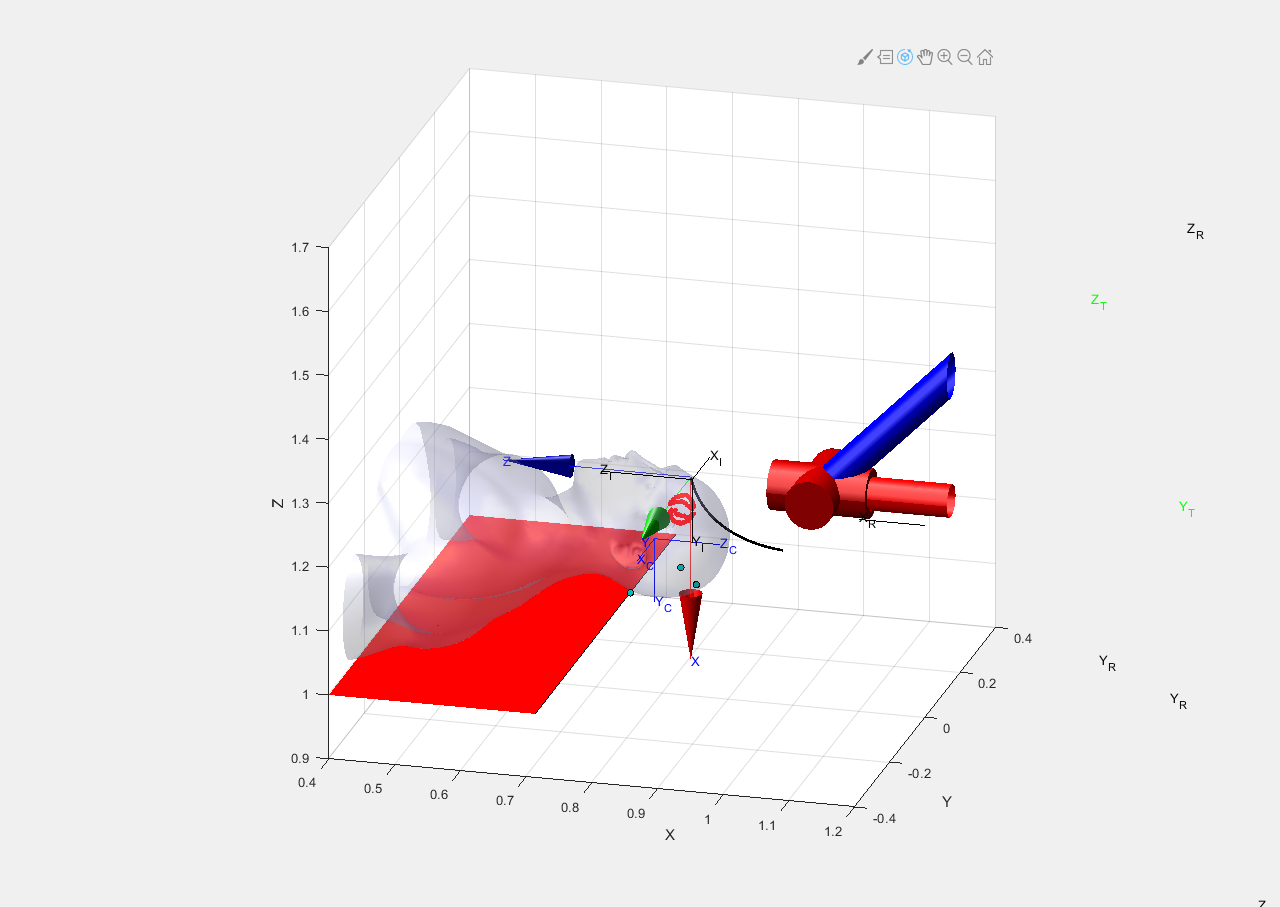


view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_burningLaser

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*We obtain the coordinates for the fiducial points in Robot space (fiducidalsRF) using the p560.teach command.*

*Then we calculate the reference frames from the triangle obtained by the 3 fiducials, in both Robot space (FR), and World space (FW).*

*Finally, we calculate the transformation matrix from FR to FW (RtoW).*

RFR = transl(1.5, -0.2, 1.35) * trotz(120, 'deg');
p560.base = RFR;

fiducidalsRF = [ 0.4891    0.4631   -0.2725;
                0.5639    0.4668   -0.2715;
                0.4883    0.5638   -0.2755];

AB=(fiducidals(1,:)-fiducidals(2,:))/norm(fiducidals(1,:)-fiducidals(2,:)); % Vector pointing A 
CB=(fiducidals(3,:)-fiducidals(2,:))/norm(fiducidals(2,:)-fiducidals(3,:)); % Vector pointing C
Z_B=cross(CB, AB)/norm(cross(CB, AB)) % Perpendicular to BA & CB equivalent to â; Z point up

Z_B =    -0.0183   -0.0277    0.9995


O_B_A =oa2r(AB, Z_B); % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis
                
AB_RF=(fiducidalsRF(1,:)-fiducidalsRF(2,:))/norm(fiducidalsRF(1,:)-fiducidalsRF(2,:)); % Vector pointing A 
CB_RF=(fiducidalsRF(3,:)-fiducidalsRF(2,:))/norm(fiducidalsRF(2,:)-fiducidalsRF(3,:)); % Vector pointing C
Z_B_RF=cross(CB_RF, AB_RF)/norm(cross(CB_RF, AB_RF)) % Perpendicular to BA & CB equivalent to â; Z point up

Z_B_RF =    -0.0148    0.0297    0.9995


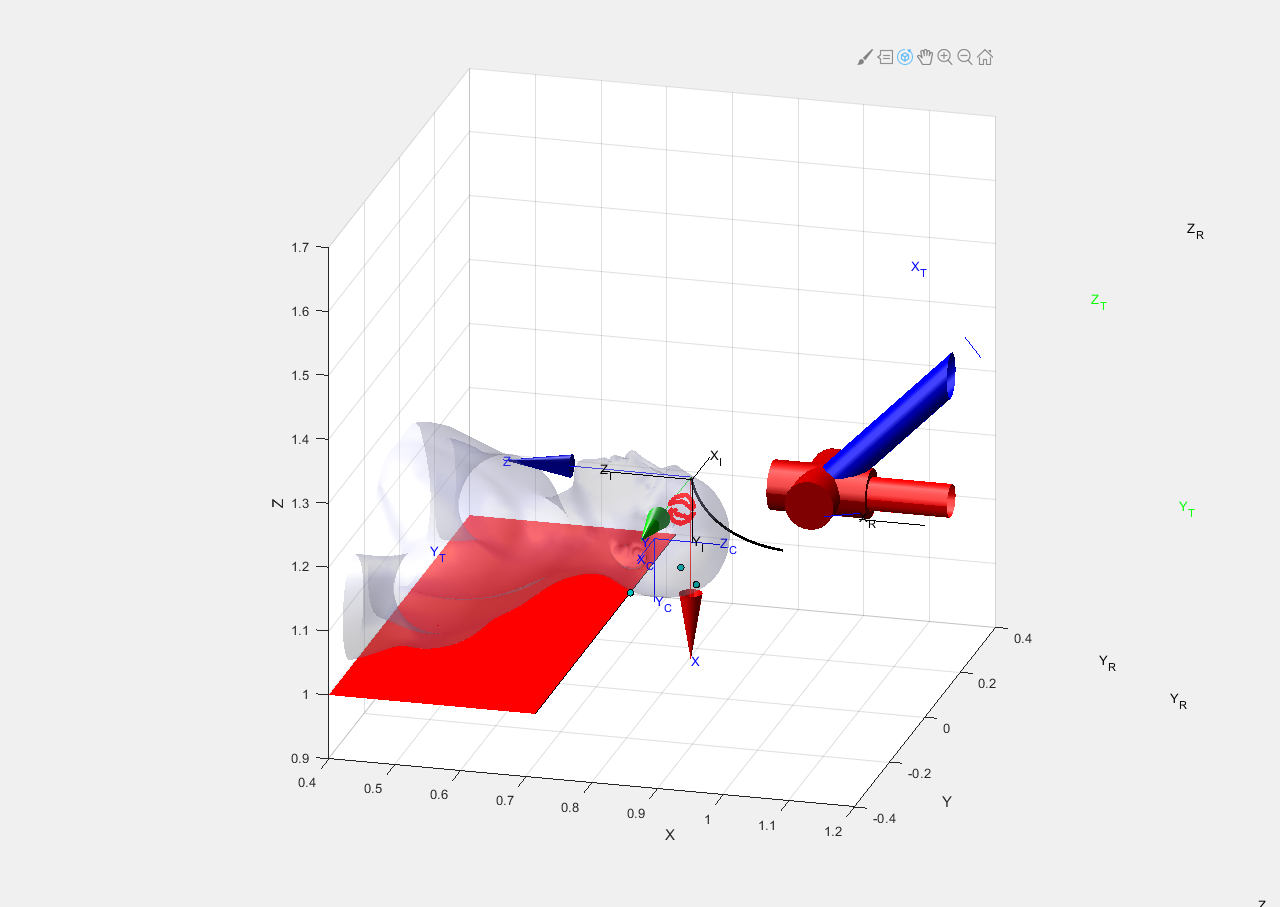

O_B_A_RF =oa2r(AB_RF, Z_B_RF); % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis

FR = [O_B_A_RF fiducidalsRF(2, :)'; 0 0 0 1];
FW = [O_B_A fiducidals(2, :)'; 0 0 0 1];

RtoW = FW*inv(FR);

trplot(RtoW, 'length', 1, 'color', 'b', 'frame', 'T')

13.- Print the tumor points in Robot Frame.

*We calculate the transformation matrix from Image space to Robot space (ItoR).*

*We load again the coordinates for the tumor points in Image space, and we apply the transformations ItoR, and RtoW, to convert the points from Image space to World space.*

ItoR = inv(RtoW) * RFI;

tumor = load('tumor.csv');

t_even = tumor(1:2:end, :);
t_odd = tumor(2:2:end, :);

t_n1 = [t_even(:, 1) t_odd(:, 2) t_even(:, 3)];
t_n2 = [t_odd(:, 1) t_even(:, 2) t_even(:, 3)];

tumor = [tumor; t_n1; t_n2];

pointR = h2e(ItoR * e2h(tumor'))';

pointWR = h2e(RtoW * e2h(pointR'))';
tumor = pointWR;

%scatter3(pointR(:, 1), pointR(:, 2), pointR(:, 3), 12, 'r', 'filled')
pointR

pointR =     0.4960    0.4672   -0.1555
    0.5038    0.4627   -0.1665
    0.4950    0.4694   -0.1535
    0.5062    0.4629   -0.1685
    0.4939    0.4716   -0.1525
    0.5095    0.4626   -0.1695
    0.4938    0.4733   -0.1505
    0.5120    0.4628   -0.1705
    0.4945    0.4745   -0.1495
    0.5135    0.4635   -0.1735


14.-Use the script that perform a biopsy. Zoom in the scene

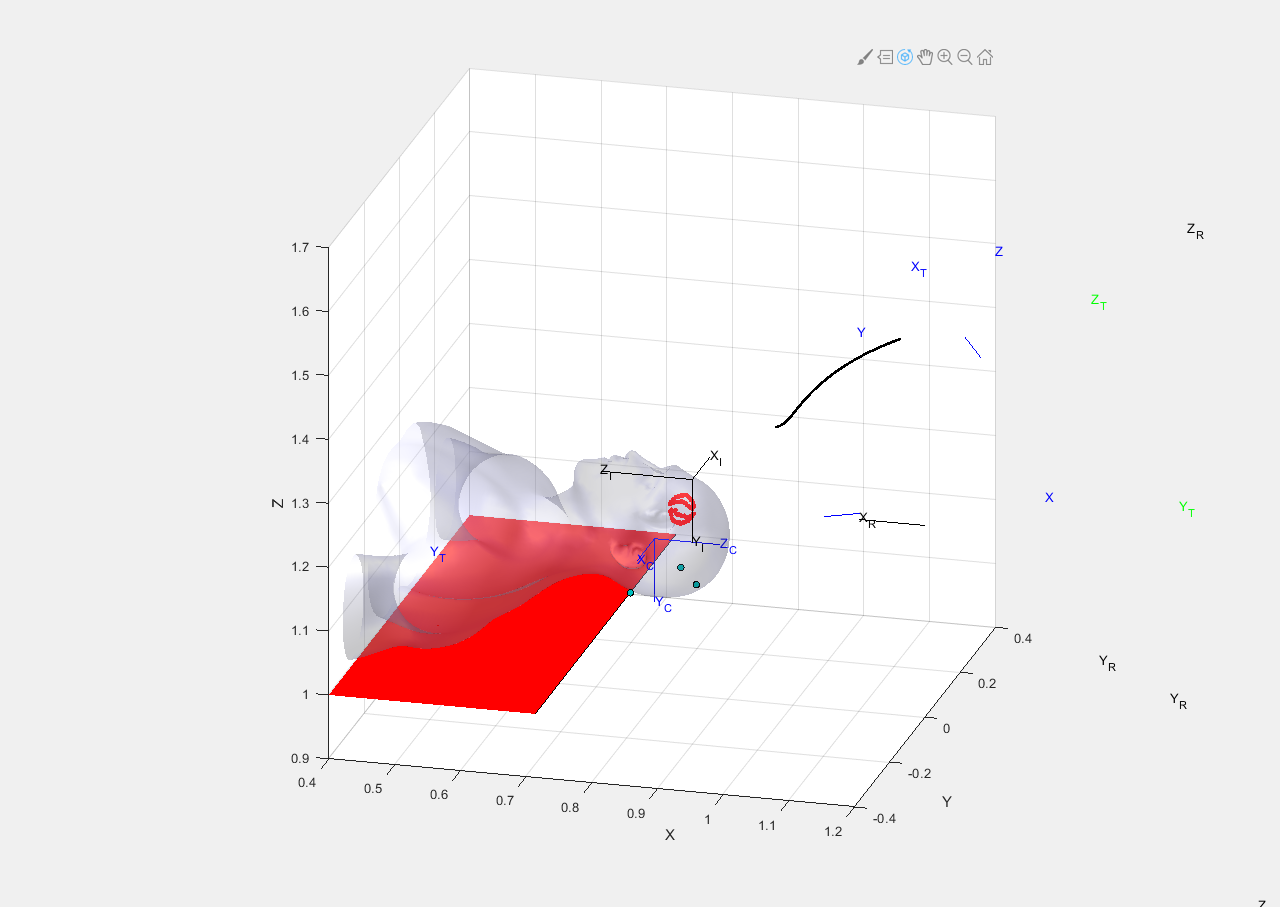

view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_biopsy

15.- Use the  script that perform trepanation.

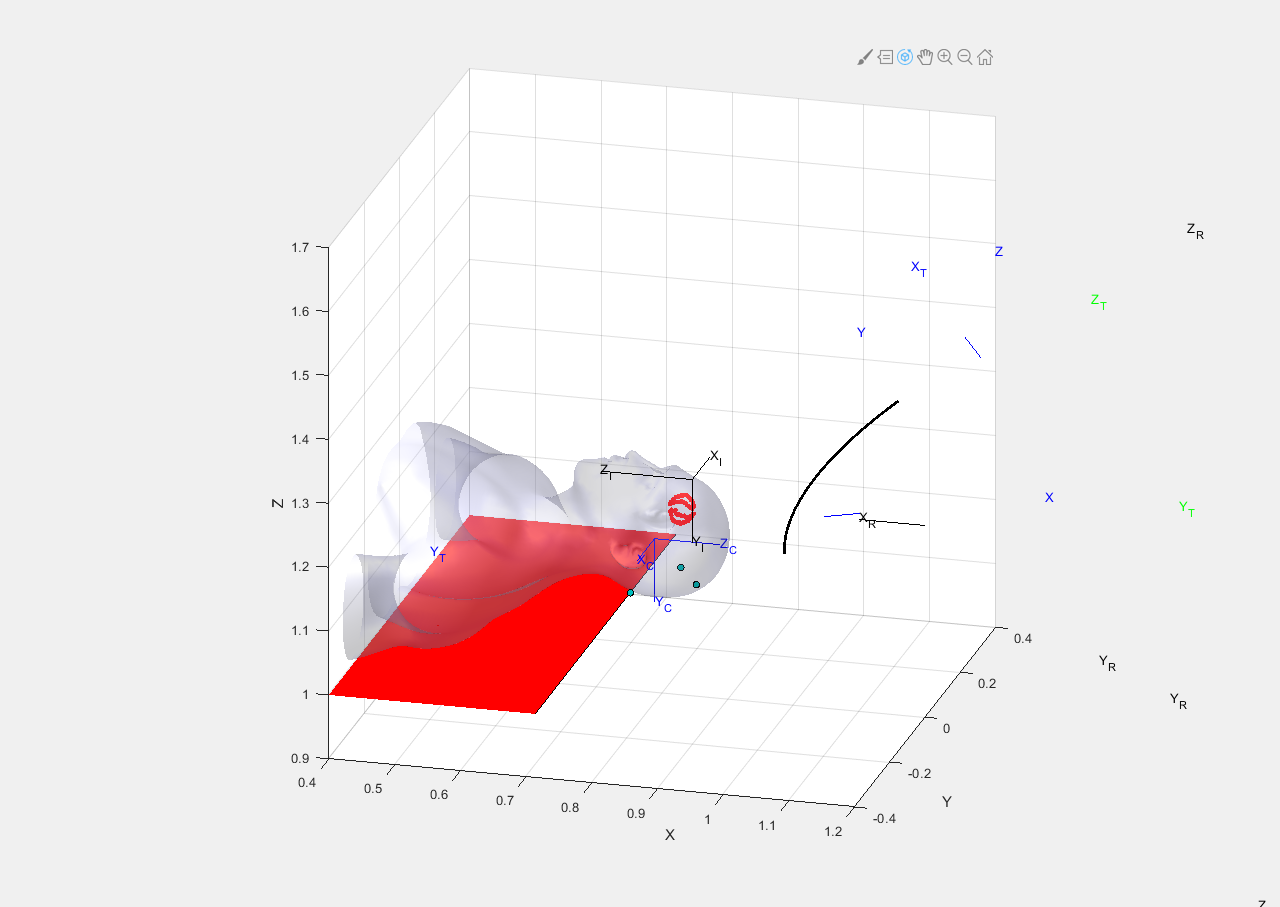

view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_trepanation

16.- Use the script that perform tumor burning with the laser.

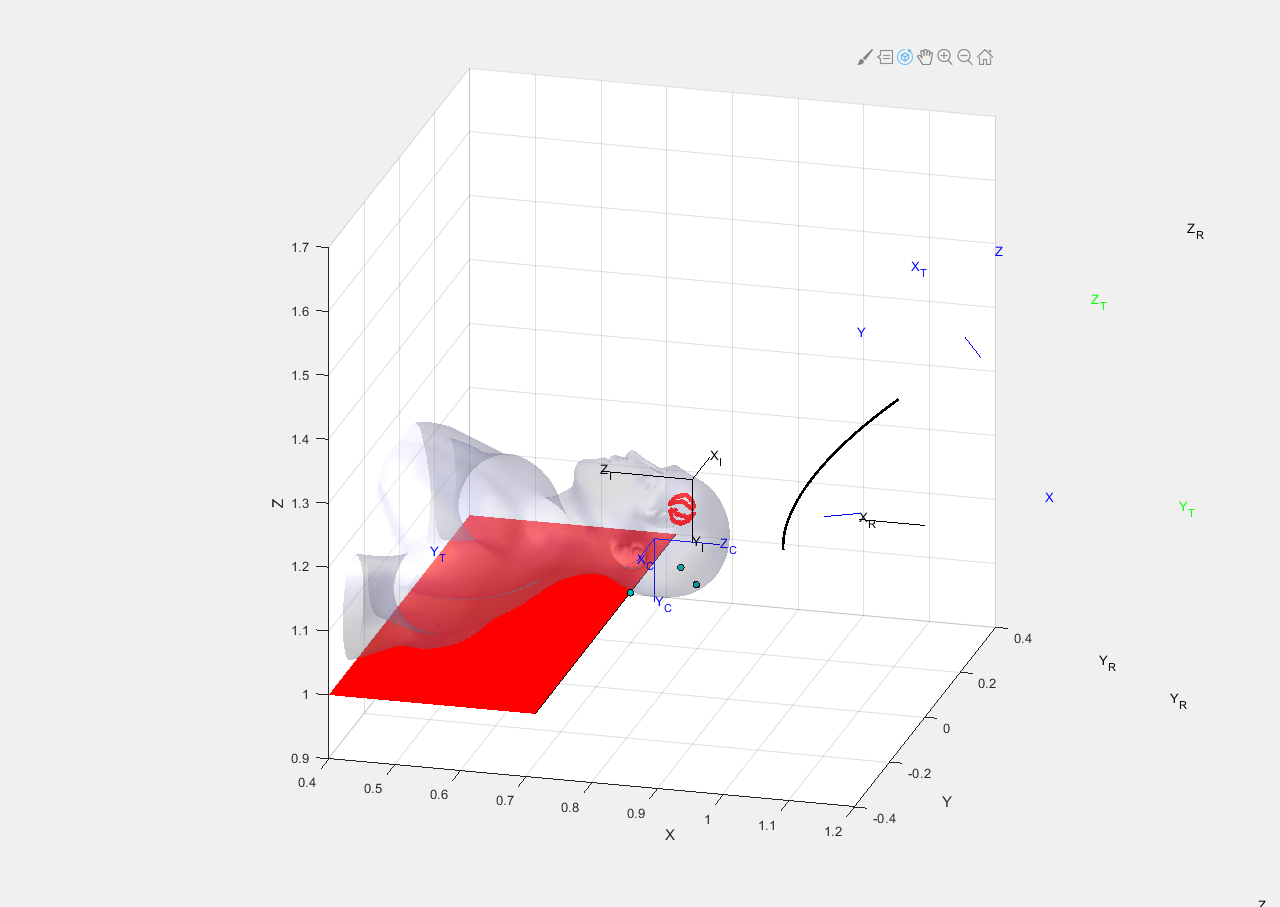

view(15, 20);
axis([-2 2 -2 2 0 4]);
task_changeTool
view(15, 20);
axis([0.4, 1.2, -0.4, 0.4, 0.9, 1.7]);
task_burningLaser